# coneEccentricitySize

Still some things wrong with cm.plot() in this tutorial.  BW to fix.

Create cone mosaics with different cone sizes and spacing corresponding to different visual field eccentricities.  The plots illustrate the impact of cone aperture and spacing changes on the cone excitations.  It also ilustrates the impact of eye movements.

ieInit;

## Eccentricity and the mosaic

This is a preview of how the cone density, aperture and spacing vary with retinal eccentricity.  We plot the variation from about 0.3 deg to 30 deg.  

These sampling properties change by more than a factor of 10 from the central fovea to 30 deg in the periphery.

This first function chooses the eccentricity and angles for the samples.  We then call the *coneSizeReadData *function which looks up the empirical data (stored in ISETBio) and interpolates them.

ecc = logspace(-0.5,1.5,20);  % Eccentricities
angles = ones(size(ecc))*90;  % Polar angles
[spacing,aperture,density] = ...
        coneSizeReadData('eccentricity',ecc, 'eccentricity units','deg', ...
                         'angle',angles,'angle units','deg',...
                         'cone density source','curcio1990');

## Plot the curves

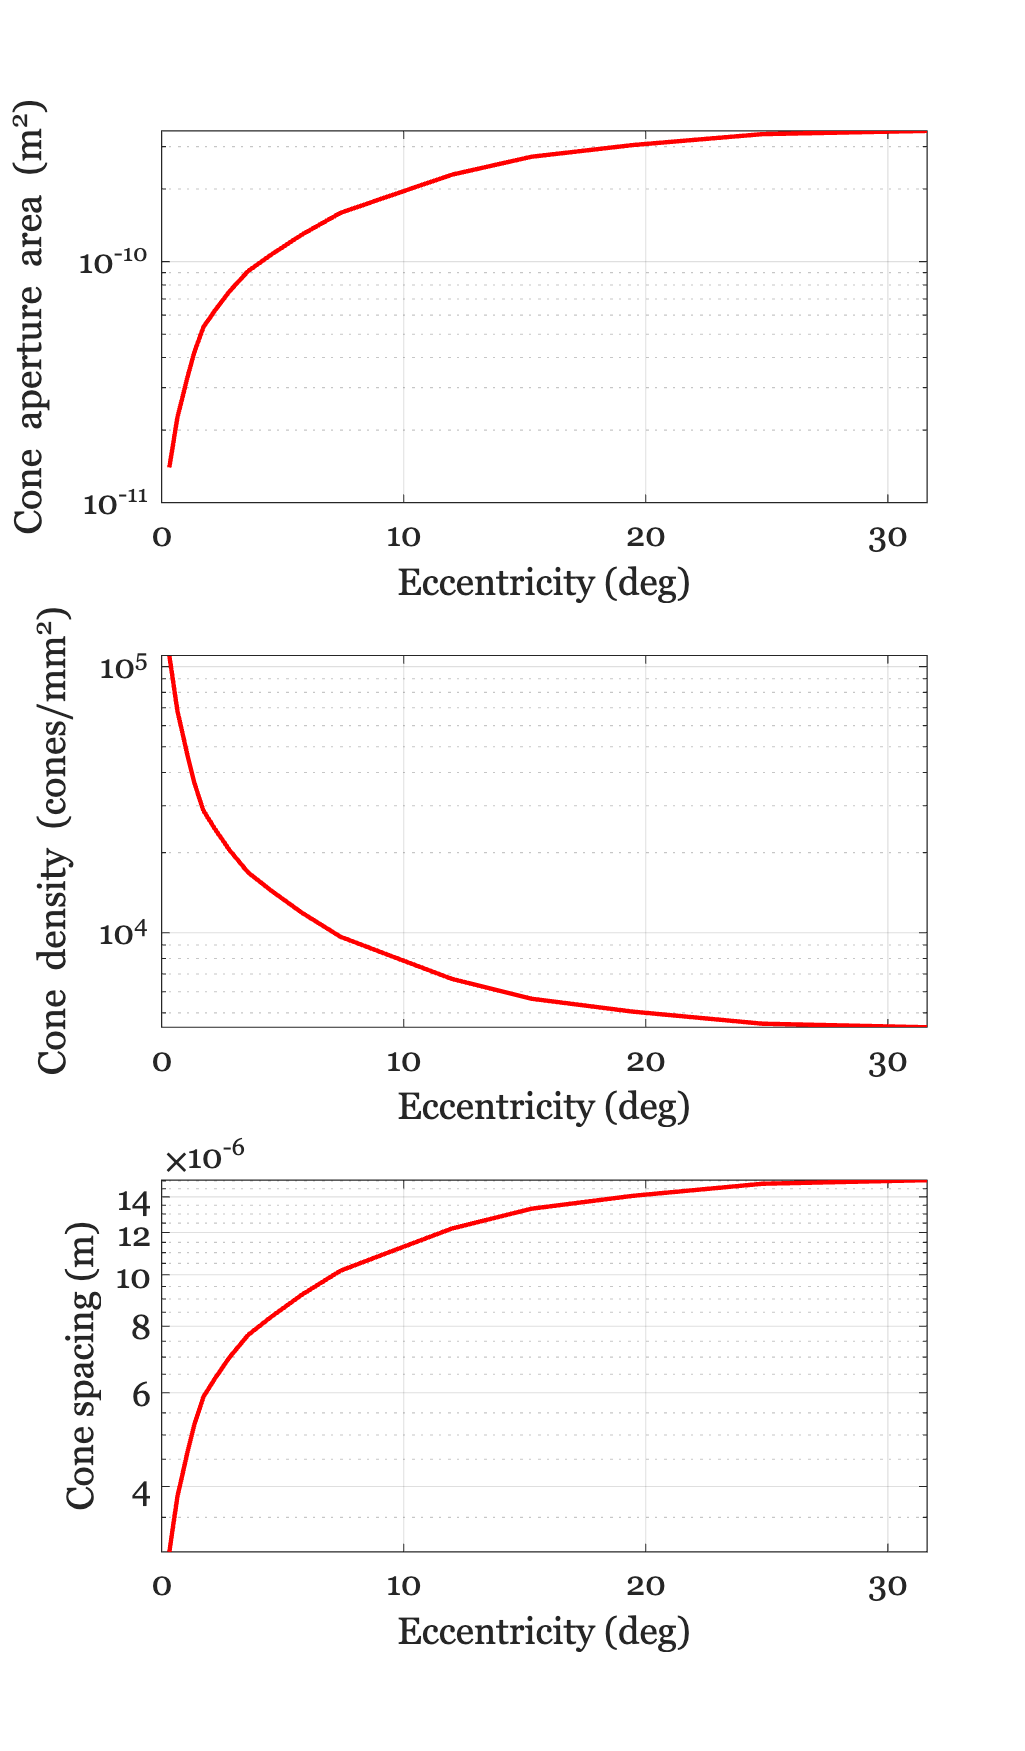

ieNewGraphWin([],'tall');
 
subplot(3,1,1); semilogy(ecc,pi*(aperture).^2,'LineWidth',2); grid on;
xlabel('Eccentricity (deg)'); ylabel('Cone aperture area (m^2)');
 
subplot(3,1,2); semilogy(ecc,density,'LineWidth',2); grid on;
xlabel('Eccentricity (deg)');ylabel('Cone density (cones/mm^2)');
 
subplot(3,1,3); semilogy(ecc,spacing,'LineWidth',2); grid on;
xlabel('Eccentricity (deg)'); ylabel('Cone spacing (m)');

## A  harmonic scene for the input stimulus

Next, create a harmonic stimulus and see the cone excitations for retinal patches at different eccentricites.  This harmonic patch is at high contrast.

hparms = harmonicP('freq',8,'contrast',1);
scene = sceneCreate('harmonic',hparms);
% sceneWindow(scene);

## The optical image

Put the stimulus through the human optics.

oi = oiCreate('human'); 
oi = oiCompute(oi,scene,'pad value','mean');
% oiWindow(oi);

## A series of human cone mosaics (fovea)

The 'center' parameter indicates the position in the mosaic we are simulating.  

cm1 = coneMosaicRect('center',[0 0],'eccentricityunits','deg');
cm1.setSizeToFOV(1);
cm1.emGenSequence(50);
cm1.compute(oi);
% cm1.window;

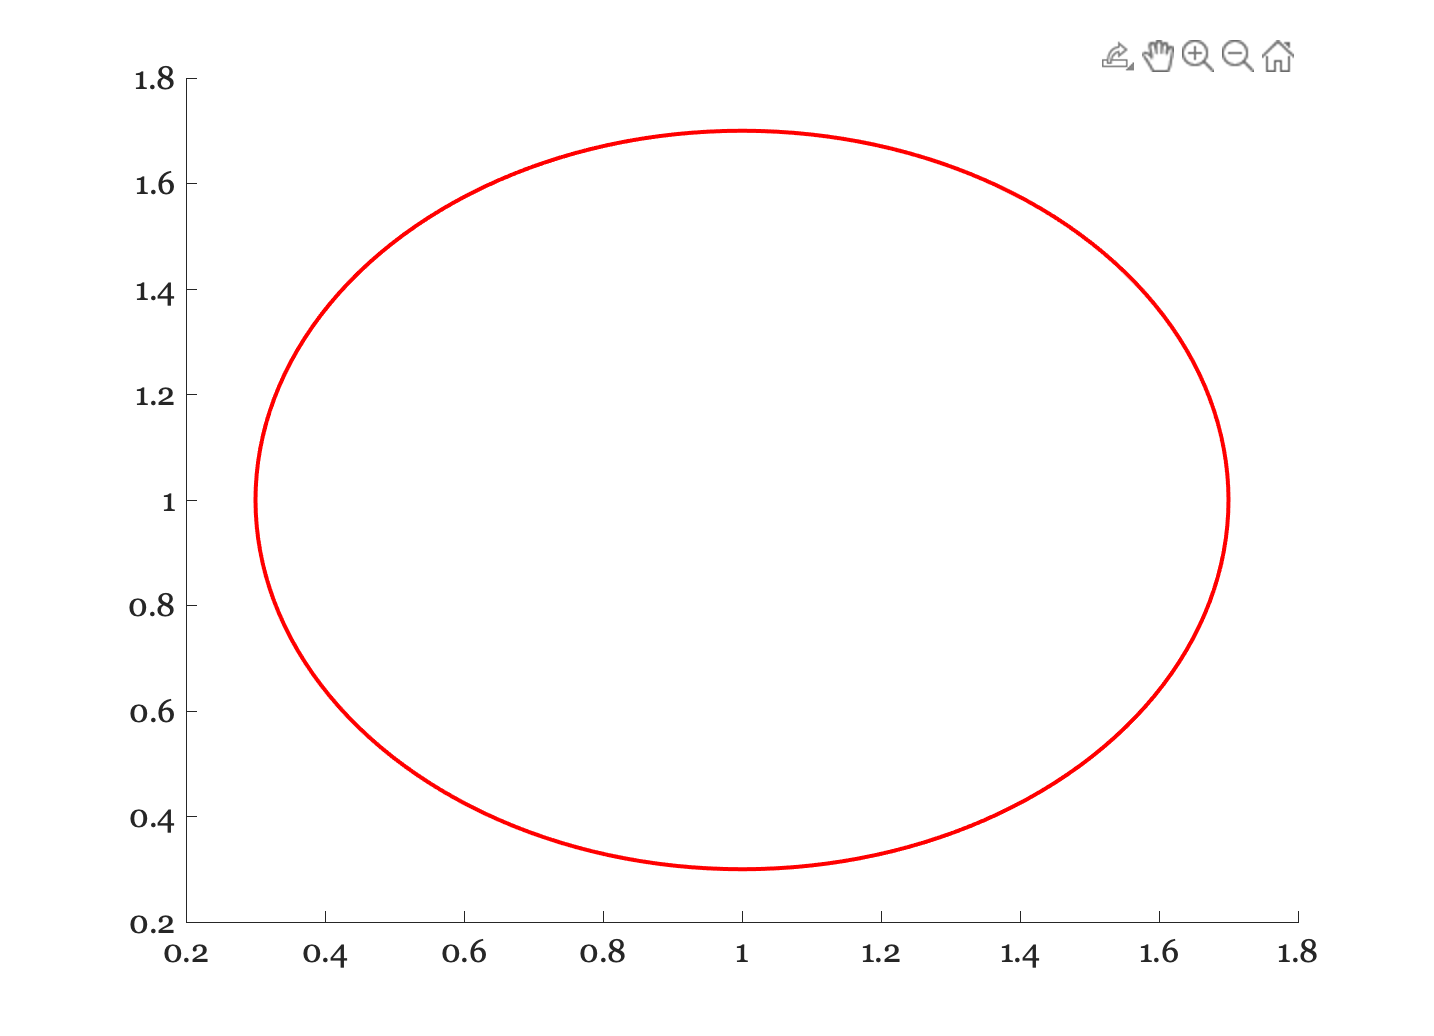

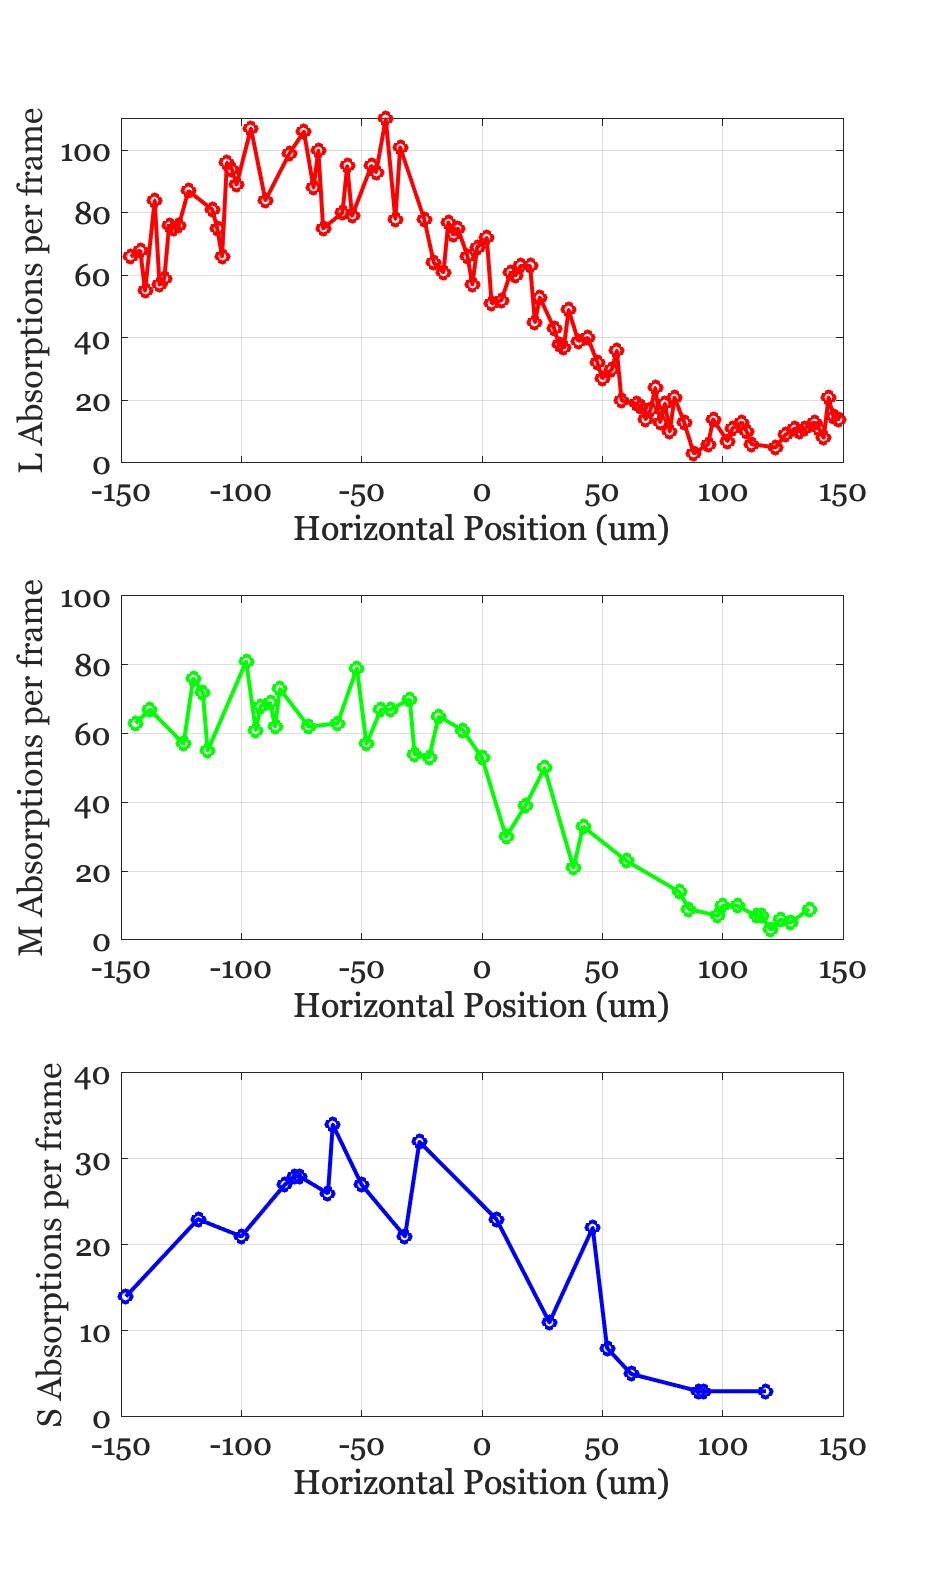

thisF = ieNewGraphWin;
cm1.plot('h line absorptions lms','xy',[1 10],'hf',thisF);

## Let's go to the movies

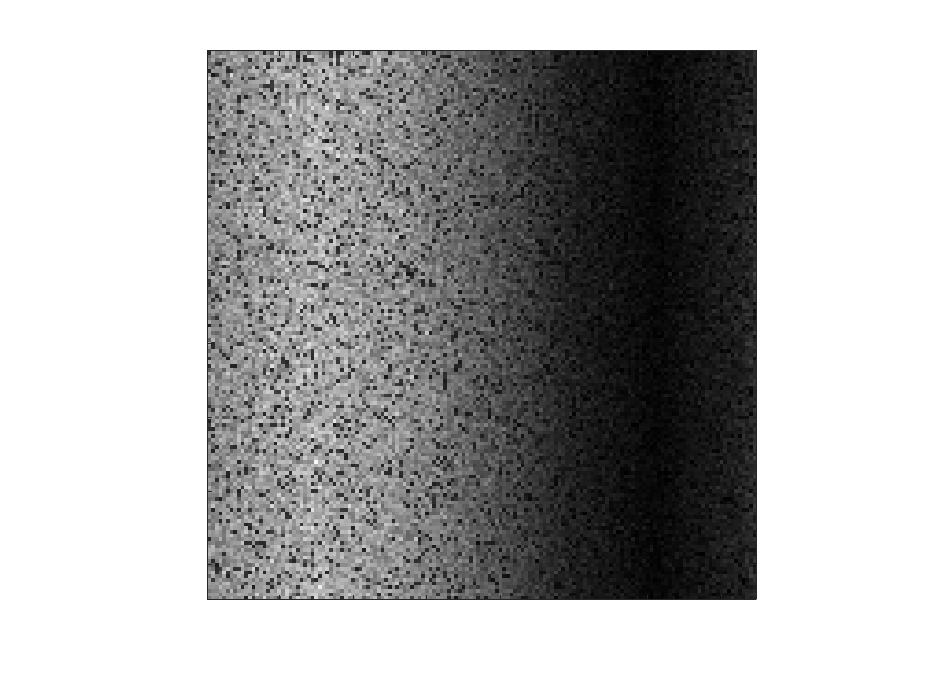

cm1.plot('movie absorptions');

## Eccentricity (10 deg)

cm2 = coneMosaicRect('center',[0 10],'eccentricityunits','deg');
cm2.setSizeToFOV(1);
cm2.emGenSequence(50);
cm2.compute(oi);
% cm2.window;

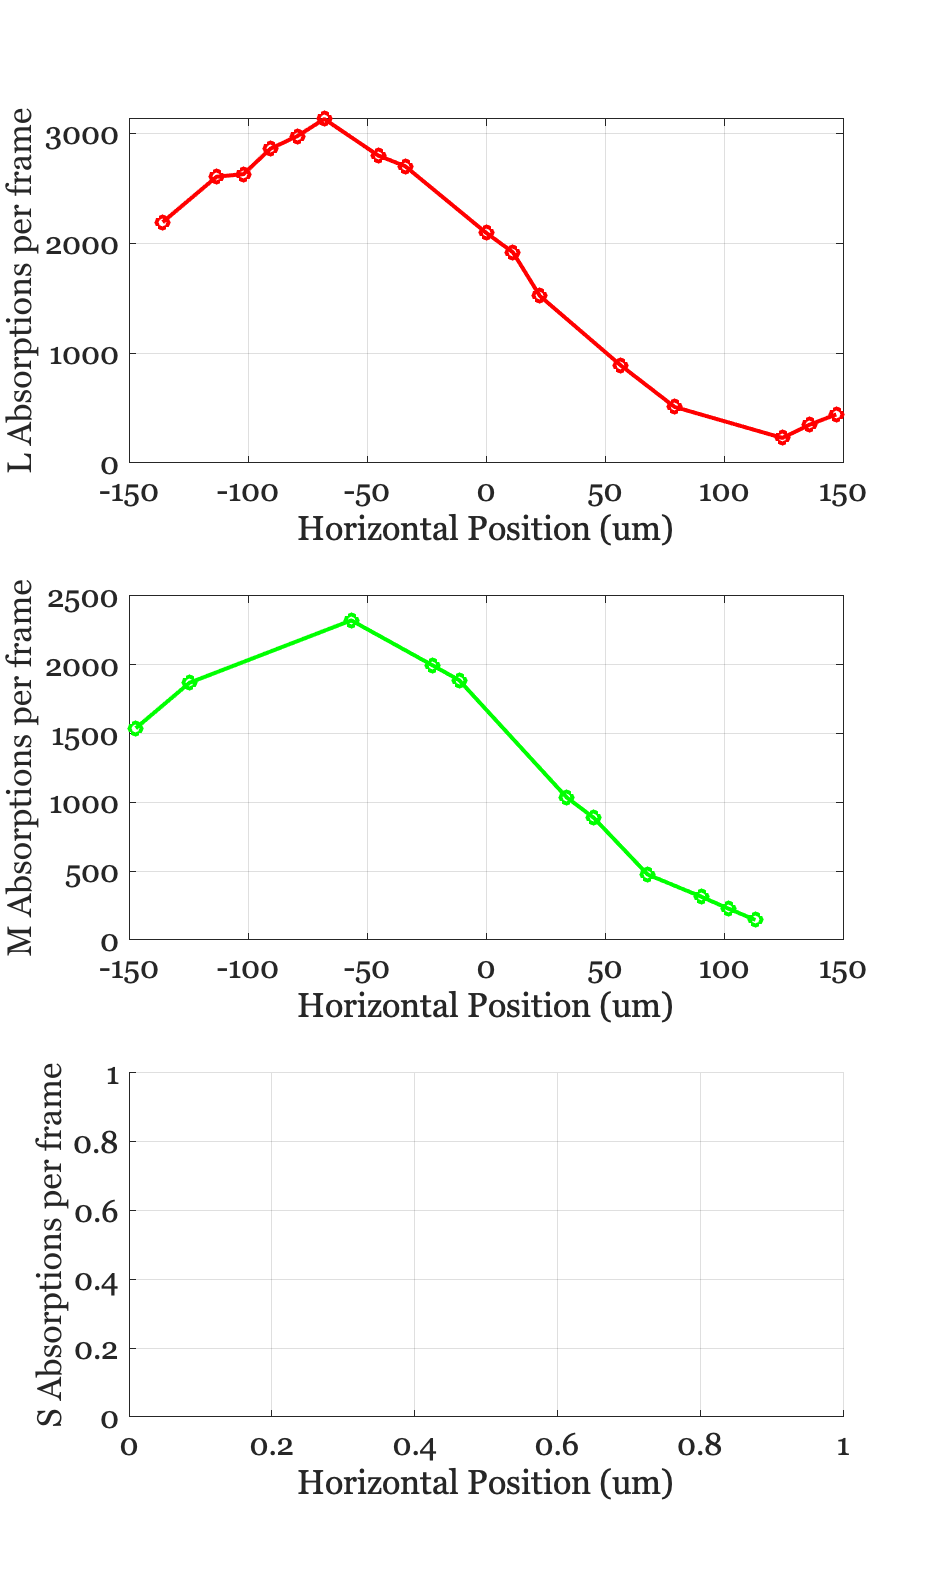

thisF = ieNewGraphWin;
cm2.plot('h line absorptions lms','xy',[1 10],'hf',thisF);

## Eccentricity (20 deg)

cm3 = coneMosaicRect('center',[0 20],'eccentricityunits','deg');
cm3.setSizeToFOV(1);
cm3.emGenSequence(50);
cm3.compute(oi);
% cm3.window;

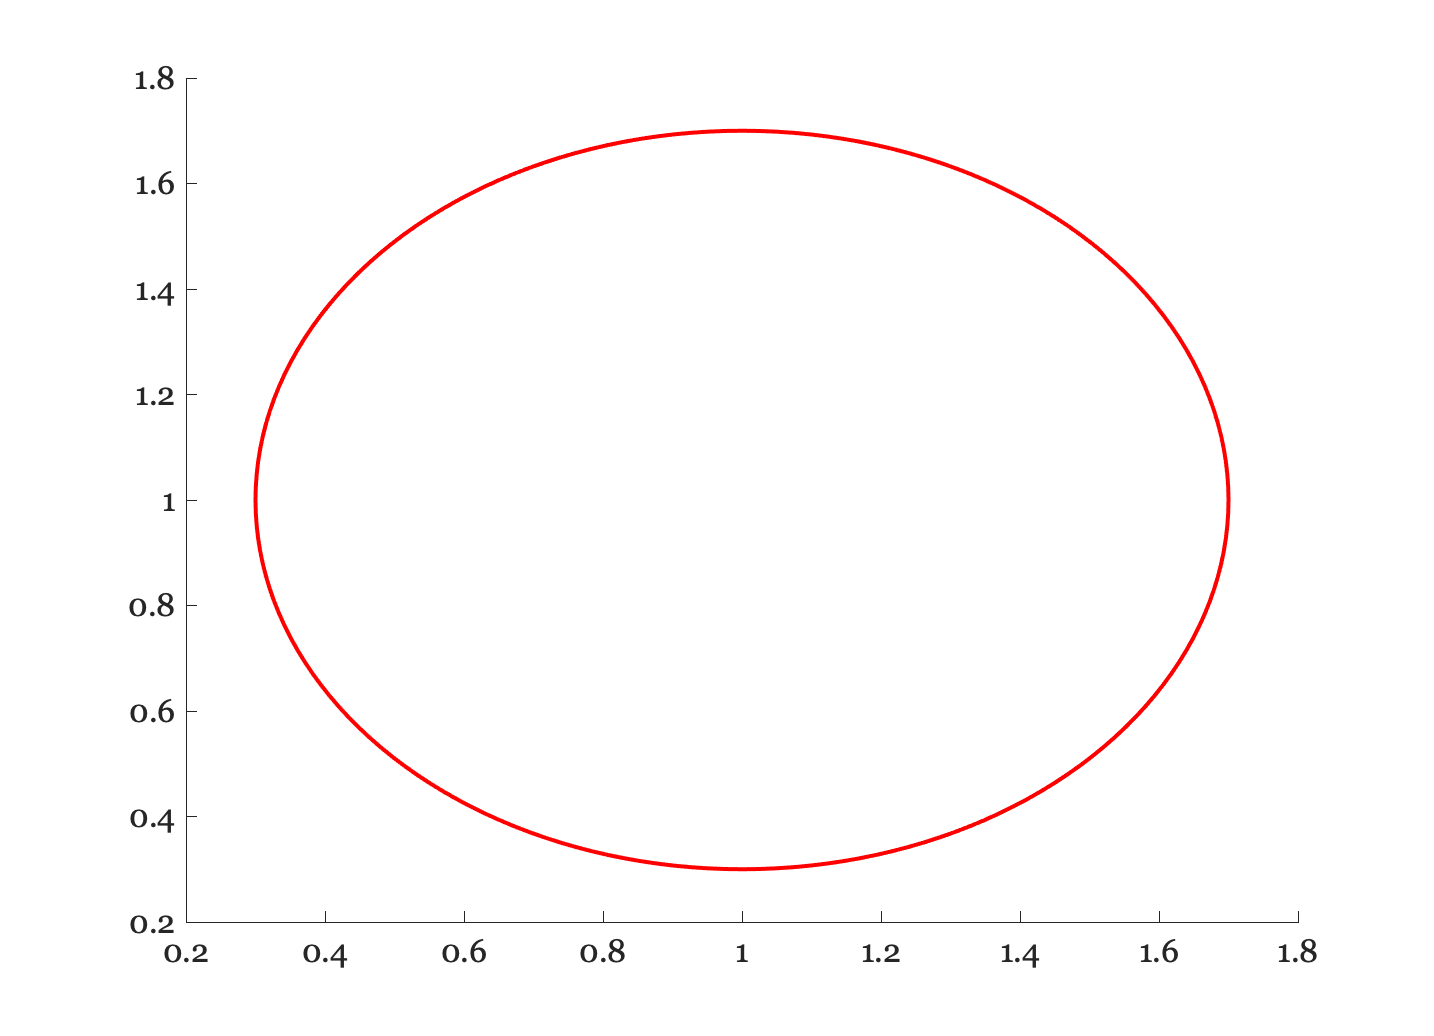

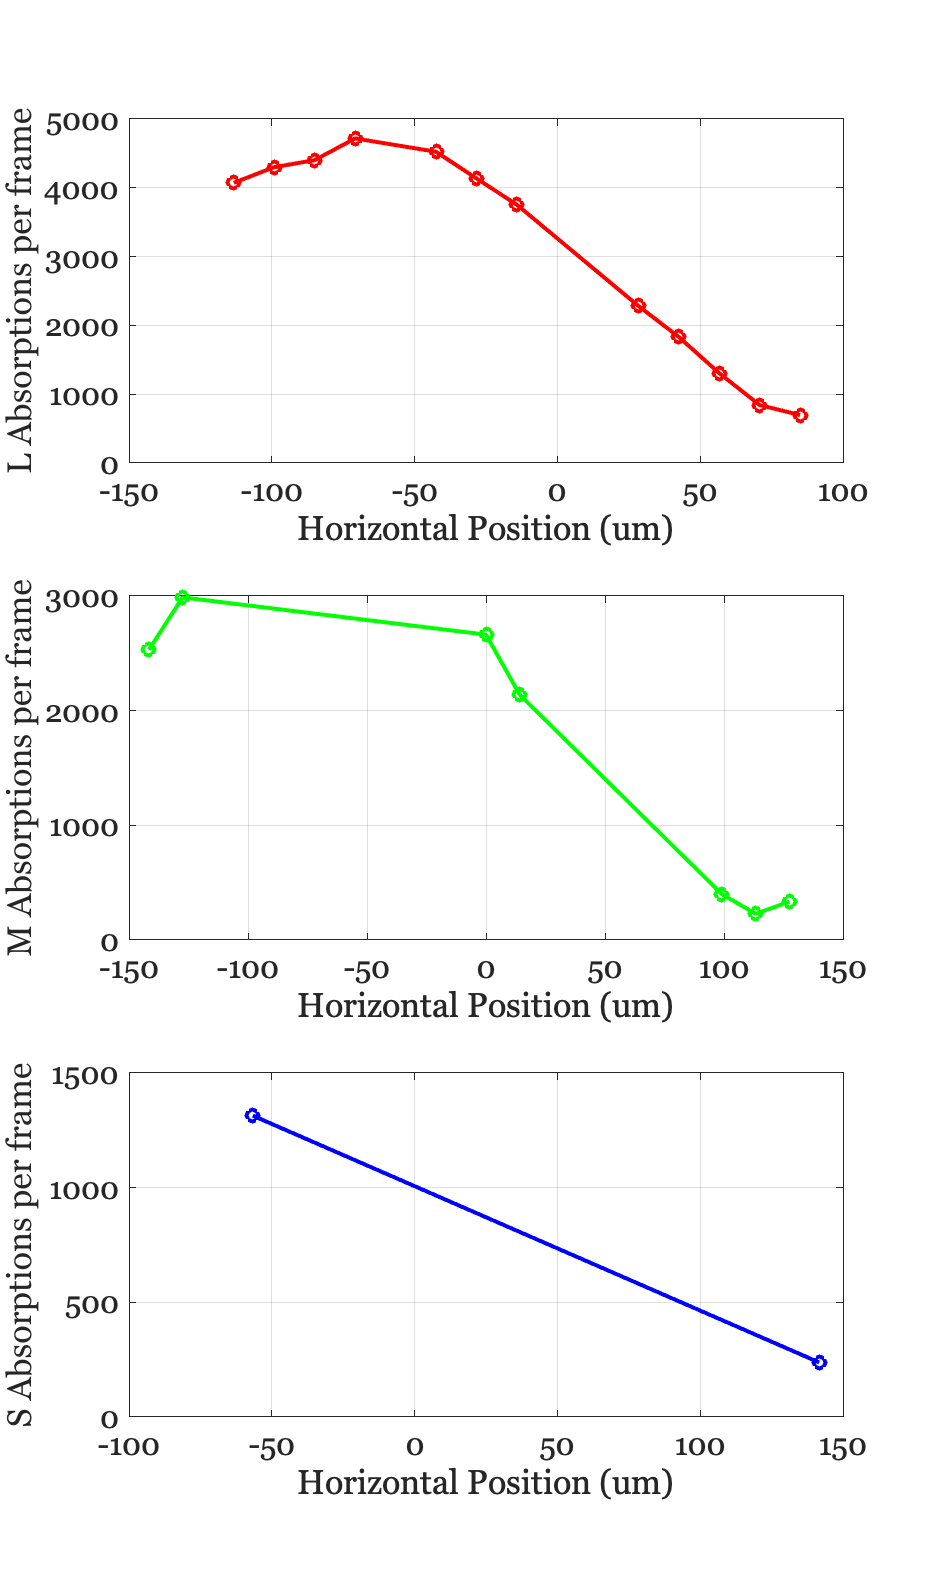

thisF = ieNewGraphWin;
cm3.plot('h line absorptions lms','xy',[1 10],'hf',thisF);

## Eye movements

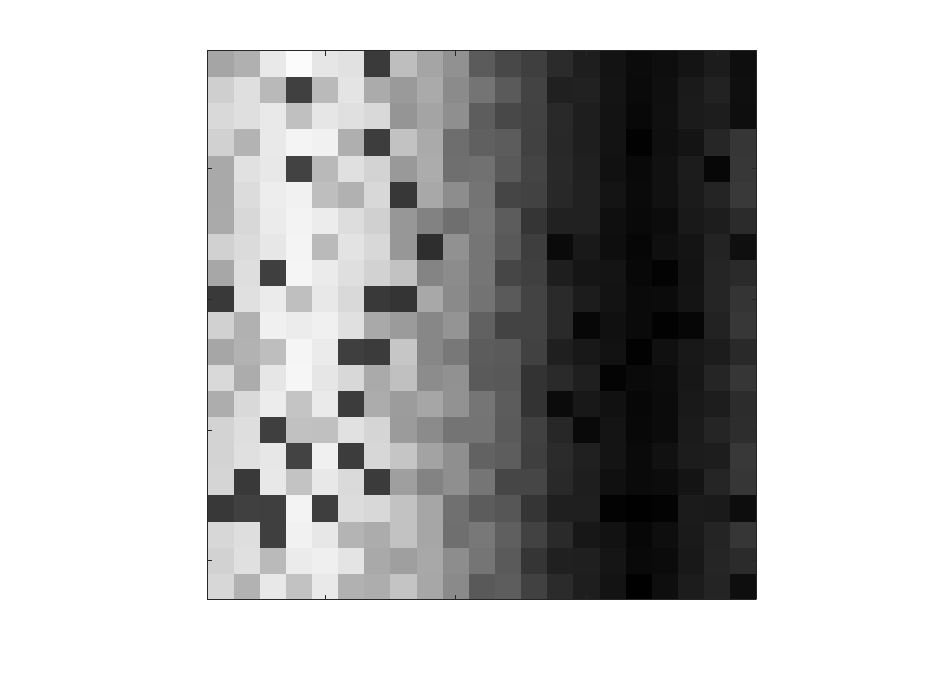

cm3.plot('movie absorptions');